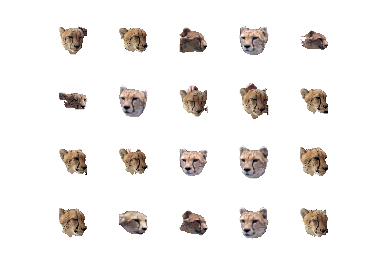

% Specify the folder where the images are stored
rootFolder = 'C:\Dataset(1)\Dataset';
% Create an imageDatastore object
imds = imageDatastore(fullfile(rootFolder, {'A', 'B', 'C', 'D', 'E'}),'LabelSource', 'foldernames', 'IncludeSubfolders', true);

% Display some example images
figure;
perm = randperm(500);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end


% Split the data into training (80%) and validation (20%) sets
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');

% Resize the training and validation images
inputSize = [224 224 3];
augimdsTrain = augmentedImageDatastore(inputSize, imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize, imdsValidation);